% conditionare pentru (x - 1)(x - 2)...(x - n) = 0
r = 1:20;
polinom1 = poly(r);
condpol(polinom1, r);

   1.0e+13 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0069    0.0392    0.1682    0.5557    1.4194    2.8523    4.4307    5.4010    5.0243    3.5438    1.8121    0.6380    0.1378    0.0138



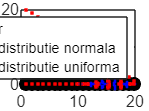


figure(1)
nn = length(r);
h = plot(r, zeros(1, nn), 'k.');
set(h, 'Markersize', 21);
hold on;

% perturbatii 
for i = 1:20
    % distributie normala 
    polinom1_pert_norm = polinom1 + normrnd(0, 1e-10, 1, length(polinom1));
    % calculam radacinile
    r_norm = roots(polinom1_pert_norm);

    h2 = plot(r_norm, 'b.');
    hold on;
    set(h2, 'Markersize', 4);

    % distributie uniforma
    polinom1_pert_unif = polinom1 + unifrnd(0, 1e-10, 1, length(polinom1));
    r_unif = roots(polinom1_pert_unif);

    h3=plot(r_unif, 'r*');
    hold on;
    set(h3, 'Markersize', 2);
end
legend('r', 'distributie normala', 'distributie uniforma');
hold off;


% pentru a^k = 2^(-k)
polinom2 = 2.^-(1:20);
condpol(polinom2)

    0.2972
    0.2972
    0.5871
    0.5871
    0.8626
    0.8626
    1.1168
    1.1168
    1.9000
    1.8766
    1.8766
    1.8070
    1.8070
    1.6929
    1.6929
    1.5371
    1.5371
    1.3435
    1.3435



ans =     0.2972
    0.2972
    0.5871
    0.5871
    0.8626
    0.8626
    1.1168
    1.1168
    1.9000
    1.8766


r2 = roots(polinom2);

figure(2)
nn = length(r2);
h = plot(r2, zeros(1, nn), 'k.');

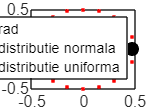

set(h, 'Markersize', 21);
hold on;

for i = 1:20
    % distributie normala
    polinom2_pert_norm = polinom2 + normrnd(0, 1e-10, 1, length(polinom2));
    r_norm = roots(polinom2_pert_norm);

    h2=plot(r_norm,'b.');
    hold on;
    set(h2, 'Markersize', 4);
    
    % distributie uniforma
    polinom2_pert_unif = polinom2 + unifrnd(0, 1e-10, 1, length(polinom2));
    r_unif = roots(polinom2_pert_unif);
    h3=plot(r_unif, 'r*');
    hold on;
    set(h3, 'Markersize', 2);
end
legend('rad', 'distributie normala', 'distributie uniforma');
hold off;


% Concluzie: Pentru acest caz, punctele din cele 2 distributii sunt destul de apropiate
